# Assignment 1.1: Teaching a SCARA Second Variant (PRR)

Objective:

 - to create and to simulate a SCARA Second Variant (PRR) using the Robotics Toolbox for MATLAB by Peter Corke

disp("SCARA Second Variant")

SCARA Second Variant


syms a1 a2 a3 a4

## Step 1: Define the Link Lengths

a1 = 5;
a2 = 5;
a3 = 5;
a4 = 5;

## Step 2: Using the Prismatic and Revolute class to create the HTM

H_01 = Prismatic('offset', a1)

 
H_01 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=5


H_12 = Revolute('a', a2)

 
H_12 = 
Revolute(std): theta=q, d=0, a=5, alpha=0, offset=0


H_23 = Revolute('a', a3)

 
H_23 = 
Revolute(std): theta=q, d=0, a=5, alpha=0, offset=0


H_34 = Revolute('a', a4)

 
H_34 = 
Revolute(std): theta=q, d=0, a=5, alpha=0, offset=0



% define the following limits

H_01.qlim = [0, 10];
H_12.qlim = [-pi/2, pi/2];
H_23.qlim = [-pi/2, pi/2];
H_34.qlim = [-pi/2, pi/2];

## Step 3: Create the Manipulator via Serial Link Class

spherical_manip = SerialLink([H_01, H_12, H_23, H_34], 'name', 'SCARA Second Variant')

 
spherical_manip = 
 
SCARA Second Variant:: 4 axis, PRRR, stdDH, slowRNE              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|          0|          5|
|  2|         q2|          0|          5|          0|          0|
|  3|         q3|          0|          5|          0|          0|
|  4|         q4|          0|          5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


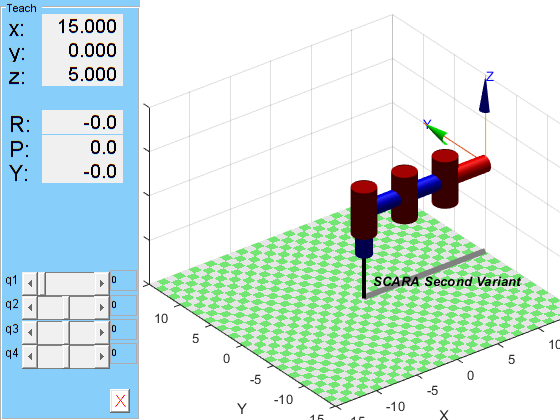


joint_setpoint = [0,0,0,0];
workspace = [-15, 15, -15, 15, -5, 15];
spherical_manip.plot(joint_setpoint, 'workspace', workspace);
spherical_manip.teach();